fs = 10e6; % Baseband Sampling Rate (65105 to 61.44e6 Hz)
frame_size = 16e3; % Samples per Each Frame (< 2^20)
% Transmitter Parameters
tx_fc = 2400e6; % Set Transmitter Center Frequency 
% (AD9363: 325-3800MHz) (AD9364: 70-6000MHz)
tx_gain = 0; % Set Transmitter Attenuation as a Negative Gain 
% (-89.75 to 0 dB)
tx_address = 'usb:0'; % Set Transmitter Identification Number
% Receiver Parameters
rx_fc = 2400e6 + 100e3; % Set Receiver Center Frequency 
% (AD9363: 325-3800MHz) (AD9364: 70-6000MHz)
rx_gain = 20; % Set Receiver Gain (-4dB to 71dB)
rx_address = 'usb:0'; % Set Receiver Identification Number
% Initialize ADALM-PLUTO
dev = sdrdev('Pluto'); % Create Radio Object for ADALM-PLUTO
% setupSession(dev)
% configurePlutoRadio('AD9363'); % Configure ADALM-PLUTO Radio Firmware
% Define Transmitter Object
tx = sdrtx('Pluto','RadioID',tx_address); % CreateTransmitterSystem Object
tx.CenterFrequency = tx_fc; % Set Transmitter Center Frequency
tx.Gain = tx_gain; % Set Transmitter Gain
tx.BasebandSampleRate = fs; % Set Baseband Sampling Rate
% Define Receiver Object
rx = sdrrx('Pluto','RadioID',rx_address); % Create Receiver System Object
rx.CenterFrequency = rx_fc; % Set Receiver Center Frequency
rx.BasebandSampleRate = fs; % Set Baseband Sampling Rate 
rx.SamplesPerFrame = frame_size; % Samples per Each Frame (< 2^20)
rx.GainSource = 'Manual'; % AGC Settings
rx.Gain = rx_gain; 
rx.OutputDataType = 'double'; % Output Data Type
stop_time = 120;

rng(1);
dcl_init;
hder_bit = repmat(reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958DC5']'))', [], 1),1,k);
[b_tx] = bit_gen(pkt_size - length(hder_bit),k);
b_tx = [hder_bit; b_tx];
encode_gray_flg = 0;
b_gray = gray_code(k,encode_gray_flg)

b_gray =      0     0
     0     1
     1     0
     1     1


sym_idx=symidx(b_tx,b_gray)

sym_idx =      3
     0
     0
     0
     0
     0
     3
     3
     0
     3


[cons, Es_avg] = constellation(M,modulation)

cons =    1.0000 + 0.0000i
   0.0000 + 1.0000i
  -1.0000 + 0.0000i
  -0.0000 - 1.0000i


Es_avg = 1

sym_mod = symmode(sym_idx,cons) 

sym_mod =   -0.0000 - 1.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
  -0.0000 - 1.0000i
  -0.0000 - 1.0000i
   1.0000 + 0.0000i
  -0.0000 - 1.0000i


[smpl_tx, cons] = pulse_modulation(sym_idx,modulation, ...
                                            M, fs, smpl_per_symbl, ...
                                               pulse_name ,pulse_gen_mode)

smpl_tx =    0.0000 + 0.0000i
  -0.0000 - 0.1508i
  -0.0000 - 0.3015i
  -0.0000 - 0.4523i
  -0.0000 - 0.6030i
  -0.0000 - 0.4523i
  -0.0000 - 0.3015i
  -0.0000 - 0.1508i
   0.0000 + 0.0000i
   0.1508 + 0.0000i


cons =    1.0000 + 0.0000i
   0.0000 + 1.0000i
  -1.0000 + 0.0000i
  -0.0000 - 1.0000i



% Transmit Repeat
f_offset = 1e6;
tx.transmitRepeat(smpl_tx);

## Establishing connection to hardware. This process can take several seconds.


## Waveform transmission has started successfully and will repeat indefinitely. 
## Call the release method to stop the transmission.


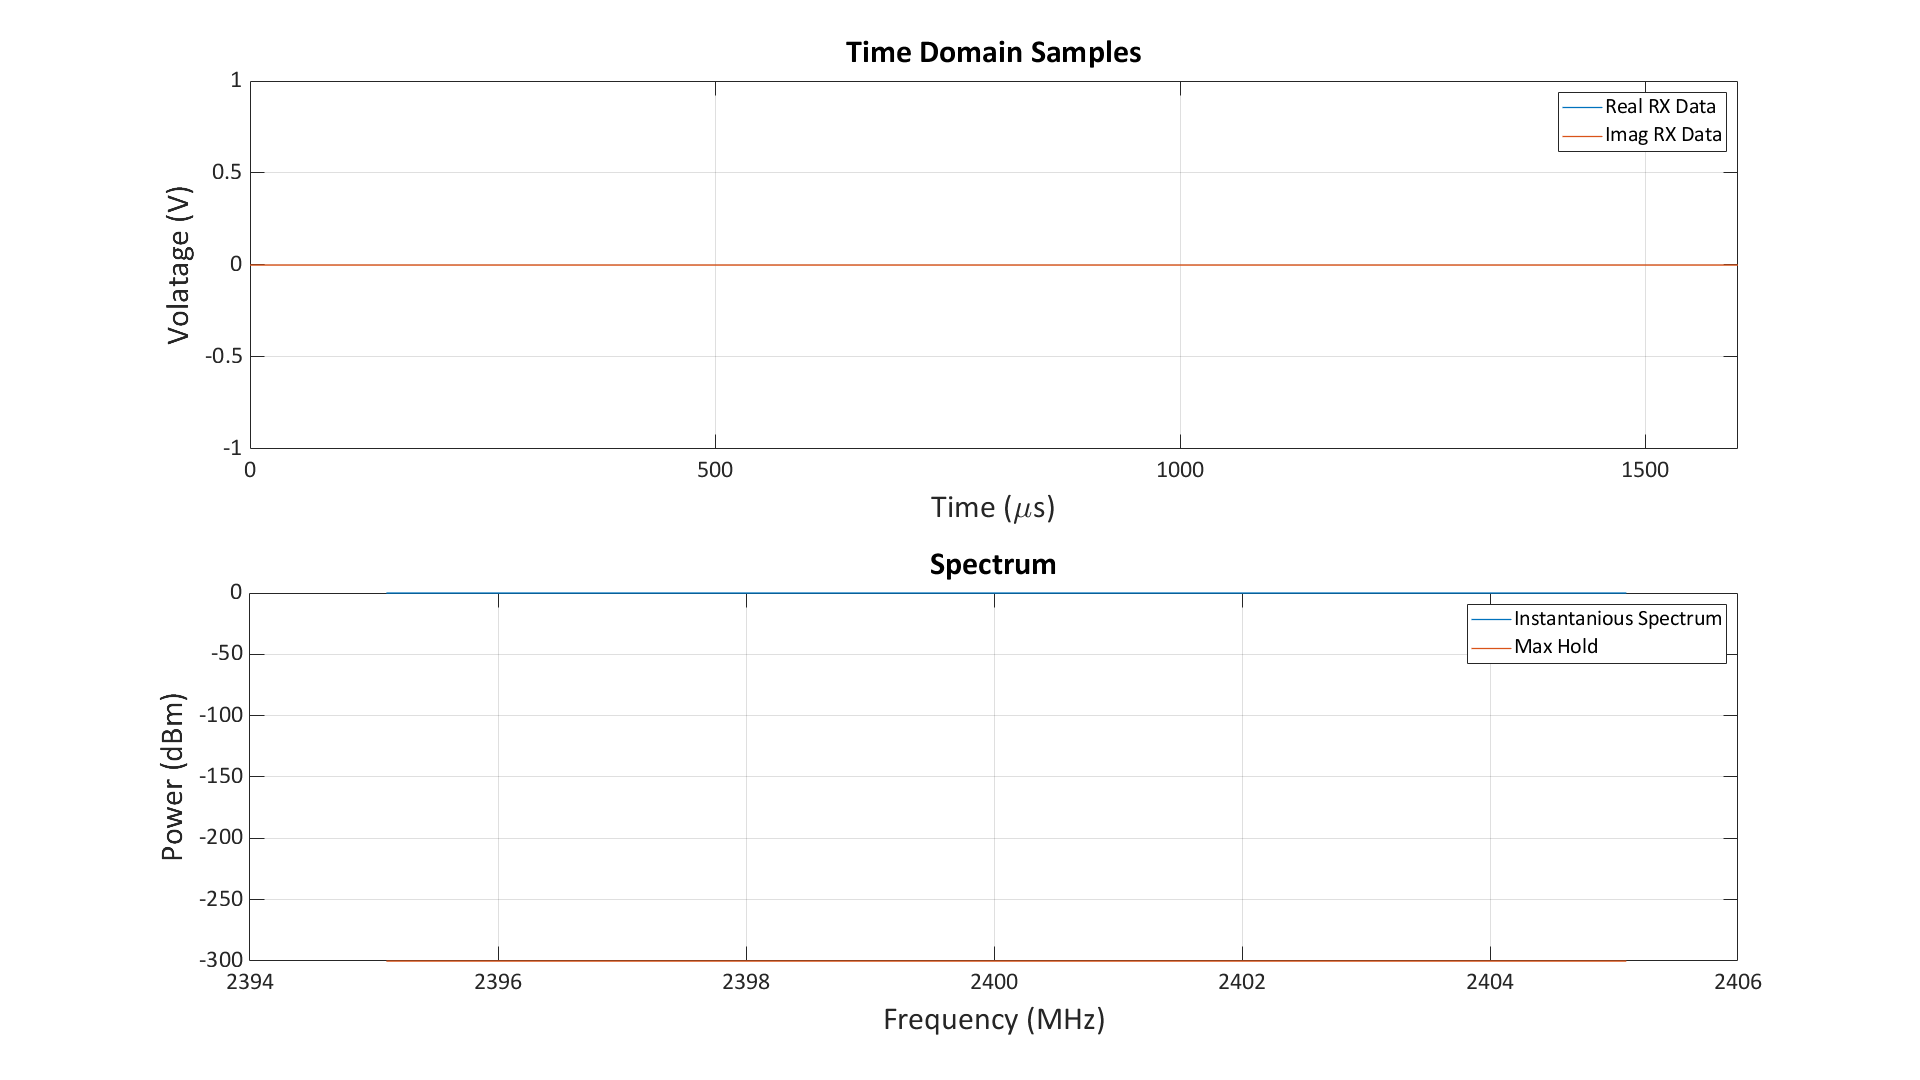

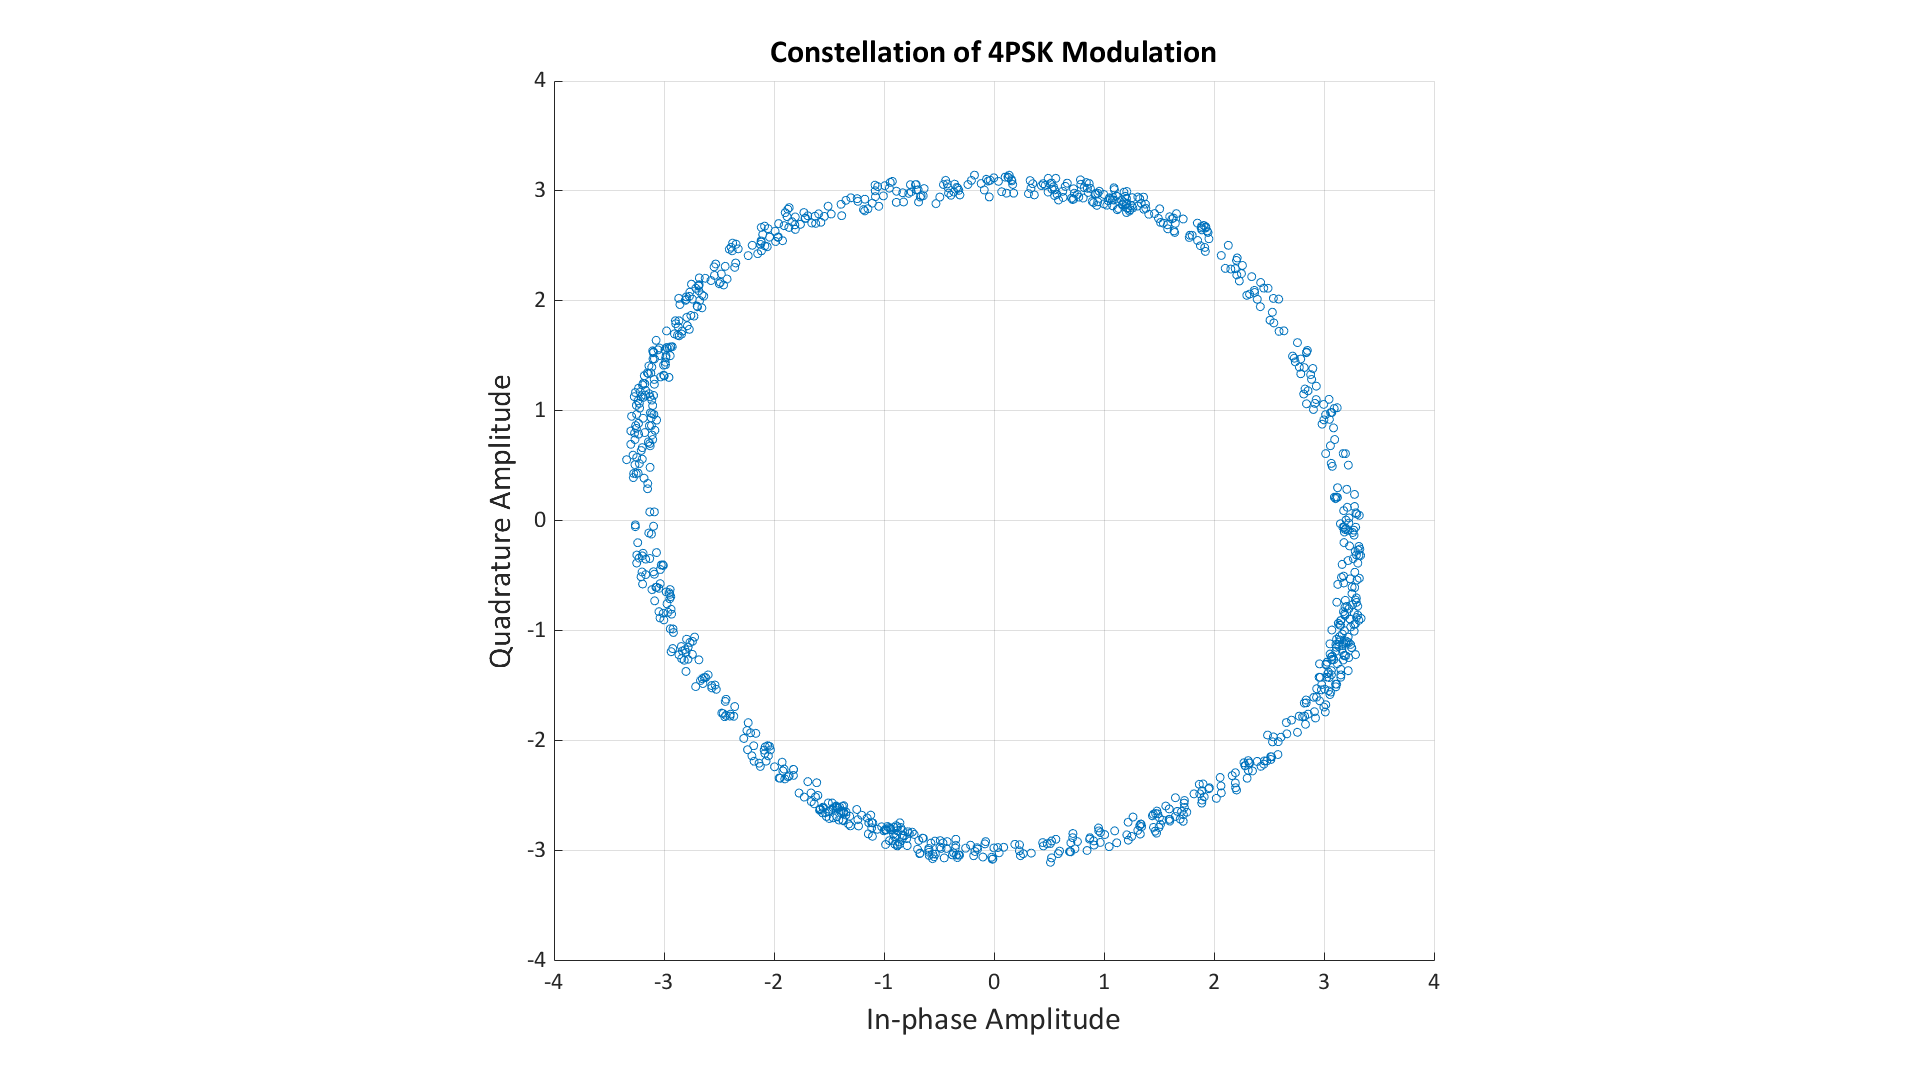

tic;

%% Plot Template

freq = (0:frame_size-1)'/frame_size*fs - fs/2 + rx_fc;
time = (0:frame_size-1)'/fs;

rx_data_real = zeros(size(freq));
rx_data_imag = zeros(size(freq));
rx_fft_dBm = zeros(size(freq));
rx_fft_dBm_max = zeros(size(freq))-300;

fig1 = figure('units','normalized','outerposition',[0 0 1 1]);

sp1 = subplot(2,1,1);

p1 = plot(time*1e6, rx_data_real, 'Parent', sp1, 'DisplayName','Real RX Data', 'LineWidth' , 1);
hold all
p2 = plot(time*1e6, rx_data_real, 'Parent', sp1, 'DisplayName','Imag RX Data', 'LineWidth' , 1);
sp1.FontName = 'Calibri';
sp1.FontSize = 18;

p1.YDataSource = 'rx_data_real';
p2.YDataSource = 'rx_data_imag';

xlabel('Time (\mus)','FontSize',24,'FontName','Calibri')
ylabel('Volatage (V)','FontSize',24,'FontName','Calibri')
title('Time Domain Samples','FontSize',24,'FontName','Calibri')
xlim([min(time), max(time)]*1e6)
legend show
grid on

sp2 = subplot(2,1,2, 'FontName','Calibri','FontSize',18);
p3 = plot(freq/1e6, rx_fft_dBm,'Parent', sp2, 'DisplayName','Instantanious Spectrum', 'LineWidth' , 1);
hold all
p4 = plot(freq/1e6, rx_fft_dBm_max, 'Parent', sp2, 'DisplayName','Max Hold', 'LineWidth' , 1);

p3.YDataSource = 'rx_fft_dBm';
p4.YDataSource = 'rx_fft_dBm_max';

sp2.FontName = 'Calibri';
sp2.FontSize = 18;

xlabel('Frequency (MHz)','FontSize',24,'FontName','Calibri')
ylabel('Power (dBm)','FontSize',24,'FontName','Calibri')
title('Spectrum','FontSize',24,'FontName','Calibri')
legend show
grid on
flg_const_plot_create = 1;
constellation_plot = 1;
R = 50;
while toc < stop_time
    rx_data = rx();
    %compensator
    lenght_header = length(hder_bit) * smpl_per_symbl;
    header_tx_smpl = smpl_tx(1:lenght_header,1);
    [corrrr , lags] = xcorr(rx_data, header_tx_smpl);
    corrrr = corrrr(lags>0);
    [amp, start_point] = max(abs(corrrr(1:8000,1)));
    rx_data = rx_data / amp;
    ang_cmpnst = angle(corrrr(start_point,1));
    rx_data = rx_data(start_point:start_point-1+frame_size/2,1);
    rx_data = rx_data * exp(-1i*ang_cmpnst);
    
    rx_data_real = real(rx_data);
    rx_data_imag = imag(rx_data);
    rx_data_no_dc = rx_data - mean(rx_data);
    
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_data,modulation, M, fs, ...
                                    smpl_per_symbl,pulse_name,rx_type,pkt_size);
if constellation_plot
            if flg_const_plot_create
                flg_const_plot_create = 0;
                fig2 = figure('units','normalized','outerposition',[0 0 1 1]);
                axes2 = axes('parent', fig2,'FontName','Calibri','FontSize',18);
                grid(axes2,'on');
                hold(axes2,'all');
                scatter_hndl = scatter(zeros(size(rx_sym,1),1), zeros(size(rx_sym,1),1));
%                 axis([-1.5 1.5 -1.5 1.5]);
                axis square
                xlabel('In-phase Amplitude','FontSize',24,'FontName','Calibri')
                ylabel('Quadrature Amplitude','FontSize',24,'FontName','Calibri')
                title(['Constellation of ', num2str(M),upper(modulation) , ' Modulation'],'FontSize',24,'FontName','Calibri')
                grid on
            end
            switch modulation
                case {'psk', 'pam', 'qam'}
                    scatter_hndl.XData = real(rx_sym*100);
                    scatter_hndl.YData = imag(rx_sym*100);
                    drawnow limitrate
               
            end
        end                                       
%     rx_fft = fftshift(fft(rx_data)/frame_size);
%     rx_fft_dBm = 10*log10(abs(rx_fft).^2/(2*R)*1000) - rx_gain;
%     rx_fft_dBm_max = max(rx_fft_dBm_max, rx_fft_dBm);
%     refreshdata
%     drawnow
end


function [b] = bit_gen(N,k)
b = randi([0 1],N,k);
end

function [b_gray] = gray_code(k,encode_gray_flg)

if encode_gray_flg==1
if k == 1
    b_gray = [0;1];
else
    z=zeros(2^(k-1),1);
    o = ones(2^(k-1),1);
    rec = gray_code(k-1,encode_gray_flg);
    recB =  rec(end:-1:1,:);
    b_gray = [z,rec;o,recB];
end
else
    b_gray =  0:2^k -1 ;
    b_gray = decimalToBinaryVector(b_gray);
end
end

function sym_idx = symidx(b_tx,b_gray)
sym_idx=zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    a = prod(b_tx(i,:)==b_gray,2);
    sym_idx(i) = find(a==1) - 1;
end
end

function [cons, Es_avg] = constellation(M, modulation)
modulation = lower(modulation);
switch modulation
    case 'pam'
        cons = (-(M-1):2:(M-1))';
        cons = cons/sqrt(abs(cons'*cons)/M);
        Es_avg = abs(cons'*cons)/M;
    case 'psk'
        s_i = cos(2*pi/M*(0:(M-1)))';
        s_q = sin(2*pi/M*(0:(M-1)))';
        cons = complex(s_i, s_q);
        cons = cons/sqrt(abs(cons'*cons)/M);
        Es_avg = abs(cons'*cons)/M;
        cons = cons(:);
        cons = cons/sqrt(abs(cons'*cons)/M);
        Es_avg = abs(cons'*cons)/M;
     case 'qam'
         if mod(log2(M),2) == 0
            m = (-sqrt(M) + 1 : 2 : sqrt(M) - 1).';
            cons_old = m + (1j * m).';
            cons = cons_old;
            for i =1:1:sqrt(M)
                if(mod(i,2) == 0)
                    cons(:,i) = flip(cons_old(:,i));
                else
                    cons(:,i) = (cons_old(:,i));
                end
            end
            cons = cons(:);
        else
            m1 = floor(log2(M) / 2);
            m2 = log2(M) - m1;
            cons = (-2 ^ m2 + 1 : 2 : 2 ^ m2 - 1) + ... 
                                (1j * (-2 ^ m1 + 1 : 2 : 2 ^ m1 - 1)).';
            cons = cons(:);
        end
        Es_avg = mean(abs(cons).^2);
        cons = cons / sqrt(Es_avg);
        Es_avg = mean(abs(cons).^2);
        
end
end

function [p, t] = pulse_shape(pulse_name, fs, smpl_per_symbl, varargin)
t = transpose(0:1/fs:(smpl_per_symbl-1)/fs);
Ts = smpl_per_symbl/fs;
switch pulse_name
    case 'triangular'
        p = max((Ts/2)-abs(t-(Ts/2)), 0);
        p = p / sqrt(sum(abs(p).^2));
end
end

function sym_mode = symmode(sym_idx,cons) 
for i=1:size(sym_idx,1)
    sym_mode(i,1) = cons(sym_idx(i)+1);
end
end

function [tx_out, cons] = pulse_modulation(sym_idx, modulation, ...
                                            M, fs, smpl_per_symbl, ...
                                               pulse_name , pulse_shape_mode, ...
                                               varargin)
[cons, Es_avg] = constellation(M, modulation);                                         
[p, t] = pulse_shape(pulse_name, fs, smpl_per_symbl, varargin);
sym_mode = symmode(sym_idx,cons);
sym_mode_up = upsample(sym_mode,smpl_per_symbl);
sym_mode_up = sym_mode_up(1:end-(smpl_per_symbl-1),1);
switch (pulse_shape_mode)   
    case 'kron'
        tx_out=kron(sym_mode,p);
    case 'conv'
        tx_out=conv(sym_mode_up,p);
end                                        
end

function [rx_sym] = corr_match(rx_smpl, p, smpl_per_symbl, rx_mode)
rx_sym = zeros(10,1);
switch rx_mode
    case 'correlator'
        for i=1:10 
          corrx = p'*rx_smpl(smpl_per_symbl*(i-1)+1:smpl_per_symbl*(i));
          rx_sym(i,1) = corrx;  
        end
    case 'matched_filter'
        r = conv(p(end:-1:1,1),rx_smpl);
        for (j=1:10)
         rx_sym(j,1)= r(j*smpl_per_symbl,1);   
        end
        
end
end

function [det_sym] = min_dist_detector(rx_sym,constellation)
dist = (rx_sym - constellation.').^2;
[~,det_sym] =  min(dist,[],2);
end


function [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, ...
                                    smpl_per_symbl, pulse_name , rx_mode,N, varargin)

                                
t = transpose(0:1/fs:(smpl_per_symbl-1)/fs);
Ts = smpl_per_symbl/fs;
switch pulse_name
    case 'triangular'
        p = max((Ts/2)-abs(t-(Ts/2)), 0);
        p = p / sqrt(sum(abs(p).^2));
end

rx_sym = zeros(N,1);
switch rx_mode
    case 'correlator'
        for i=1:N 
          corrx = p'*rx_smpl(smpl_per_symbl*(i-1)+1:smpl_per_symbl*(i));
          rx_sym(i,1) = corrx;  
        end
    case 'matched_filter'
        r = conv(p(end:-1:1,1),rx_smpl);
        for (j=1:N)
         rx_sym(j,1)= r(j*smpl_per_symbl,1);   
        end
        
end

switch modulation
    case 'pam'
        m = transpose(1:M);
        cons = 2 * m - 1 - M;
        Es_avg = mean(abs(cons).^2);
        cons = cons / sqrt(Es_avg);
        Es_avg = mean(abs(cons).^2);
    case 'psk'
        s_i = cos(2*pi/M*(0:(M-1)))';
        s_q = sin(2*pi/M*(0:(M-1)))';
        cons = complex(s_i, s_q);
        cons = cons/sqrt(abs(cons'*cons)/M);
        Es_avg = abs(cons'*cons)/M;
        cons = cons(:);
        cons = cons/sqrt(abs(cons'*cons)/M);
        Es_avg = abs(cons'*cons)/M;
     case 'qam'
         if mod(log2(M),2) == 0
            m = (-sqrt(M) + 1 : 2 : sqrt(M) - 1).';
            cons_old = m + (1j * m).';
            cons = cons_old;
            for i =1:1:sqrt(M)
                if(mod(i,2) == 0)
                    cons(:,i) = flip(cons_old(:,i));
                else
                    cons(:,i) = (cons_old(:,i));
                end
            end
            cons = cons(:);
        else
            m1 = floor(log2(M) / 2);
            m2 = log2(M) - m1;
            cons = (-2 ^ m2 + 1 : 2 : 2 ^ m2 - 1) + ... 
                                (1j * (-2 ^ m1 + 1 : 2 : 2 ^ m1 - 1)).';
            cons = cons(:);
        end
        Es_avg = mean(abs(cons).^2);
        cons = cons / sqrt(Es_avg);
        Es_avg = mean(abs(cons).^2);
        
end


dist = (rx_sym - cons.').^2;
[~,det_sym_idx] =  min(dist,[],2);

end

function [tx_smpl_delayed,rx_smpl,rx_smpl_noise] = channel(tx_smpl,chnl_delay_in_smpl,chnl_phase_offset,variance,N)
 temp = zeros(chnl_delay_in_smpl,1);
 tx_smpl_delayed = [temp;tx_smpl];
 rx_smpl = tx_smpl_delayed.*exp(1i*chnl_phase_offset);
 noise_smpl = sqrt(variance/2) * (randn(1,length(rx_smpl))+ 1i *randn(1,length(rx_smpl))).';
 rx_smpl_noise = rx_smpl + noise_smpl;
end

function [det_bit_dec,det_bit] = decode(det_sym_idx,encode_gray_flg,k)
    b_gray = gray_code(k,encode_gray_flg);
    det_bit = [];
    det_bit_dec = 0;
    for i=1:k
        b(:,i) = b_gray(det_sym_idx,i);
        det_bit = [det_bit b(:,i)];
        det_bit_dec = det_bit_dec + det_bit(:,i)*2;
    end
   
end